EE3510 HW1 105060012張育菘

1. 

close all; clear;

x = [2 1+2j; 
    -0.45 5];
I = [1 0;
    0 1];
z1 = 0.5*log(x+sqrt(1+x.^2)) + I;
z1

z1 =    1.7218 + 0.0000i   0.7347 + 0.5317i
  -0.2180 + 0.0000i   2.1562 + 0.0000i


2. 

A = [12 34 -4; 34 7 87; 3 65 7];
B = [1 4 7; 2 5 8; 3 6 9];

z2 = A*B;
z3 = A.*B;
z4 = A^3;
z5 = A.^3;
z6 = [A([1:3],:);B^2];
[T, E] = eig(B); z7 = E;
z8 = det(A);
z2 

z2 =           68         194         320
         309         693        1077
         154         379         604


z3

z3 =     12   136   -28
    68    35   696
     9   390    63


z4

z4 =        37226      233824       48604
      247370      149188      600766
       78688      454142      118820


z5

z5 =         1728       39304         -64
       39304         343      658503
          27      274625         343


z6

z6 =     12    34    -4
    34     7    87
     3    65     7
    30    66   102
    36    81   126
    42    96   150


z7

z7 =    16.1168         0         0
         0   -1.1168         0
         0         0   -0.0000


z8

z8 = -75246

3. 

H3 = [1/2 1/3 1/4; 1/3 1/4 1/5; 1/4 1/5 1/6];
Y = [0.95; 0.67; 0.52];
x = (H3^-1)*Y;
x1 = x(1,1); x2 = x(2, 1); x3 = x(3, 1);
fprintf('x1 = %2.2f, x2 = %2.2f, x3 = %2.2f\n', x1, x2, x3);

x1 = 1.20, x2 = 0.60, x3 = 0.60



Y = [0.95; 0.67; 0.53];
x = (H3^-1)*Y;
x1 = x(1,1); x2 = x(2, 1); x3 = x(3, 1);
fprintf('After changing 0.52 to 0.53:\n');

After changing 0.52 to 0.53:


fprintf('x1 = %2.2f, x2 = %2.2f, x3 = %2.2f\n', x1, x2, x3);

x1 = 3.00, x2 = -6.60, x3 = 6.60


4. 


$$H_{\mathrm{ij}} =\frac{1}{i+j-1},H_{\mathrm{ij}} =\int_0^1 x^{i+j-2} \mathrm{dx}$$


H4 = zeros(9,9);

for i = 1:1:9
    for j = 1:1:9
        f4 = @(x) x.^(i+j-2);
        H4(i, j) = integral(f4, 0, 1);
    end
end
H4

H4 =     1.0000    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111
    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588


5. 

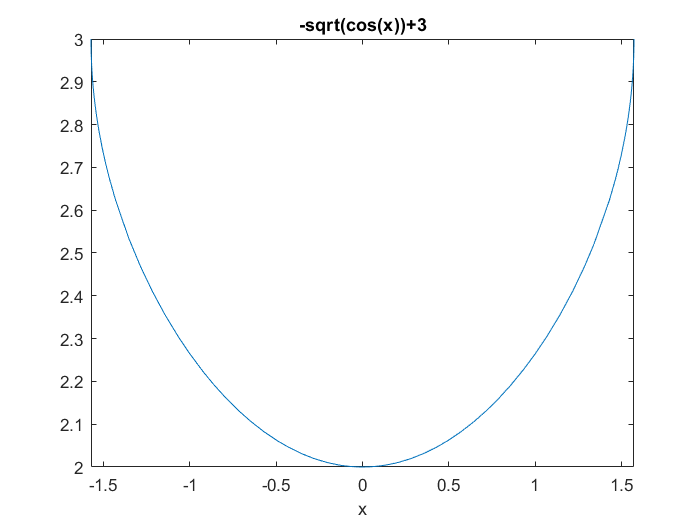

figure; 
fplot(@(x) -sqrt(cos(x))+3, [-pi/2, pi/2]);
title('-sqrt(cos(x))+3');
xlabel('x');

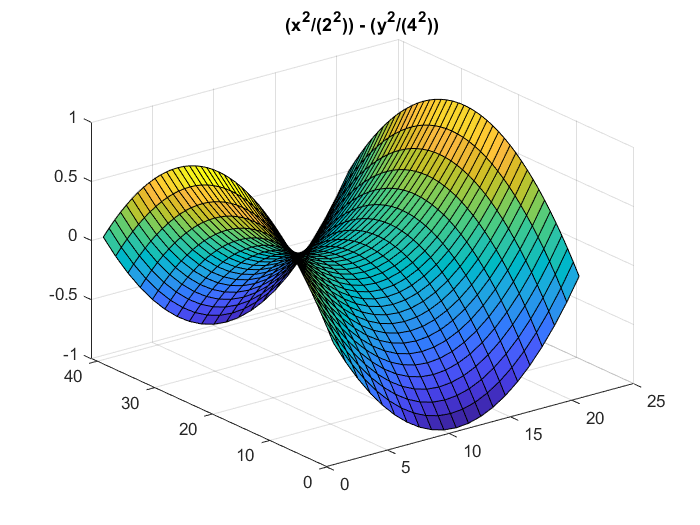


figure;
x =[-2:0.2:2];  % value x range
y =[-4:0.2:4];  % value y range
[xm, ym] = meshgrid(x,y);  % meshgrid: 2-D and 3-D grids
fxy =  (xm.^2/(2^2)) - (ym.^2/(4^2)); % Your Function  fxy=f(x,y) 
surf(fxy);   % surf : Surface plot
title('(x^2/(2^2)) - (y^2/(4^2))');